# ME2801 HW4: Textbook Exercise Solutions in MATLAB

## Nise 5.1

- See Textbook solutions for by-hand solution.  Note that the MATLAB command `minreal `simplifies the transfer function expression.

In MATLAB you need to name each transfer function block:

G1 = tf(1,[1 0 0])


G1 =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


G2 = tf(50,[1 1])


G2 =
 
   50
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


G3 = tf(2,[1 0])


G3 =
 
  2
  -
  s
 
Continuous-time transfer function.
Model Properties


G4 = tf([1 0],1)


G4 =
 
  s
 
Continuous-time transfer function.
Model Properties


G5 = 2

G5 = 2

We can combine G2 and G3 using the feedback form.  The equivalent TF is

Ge1 = feedback(G2, G3)


Ge1 =
 
      50 s
  -------------
  s^2 + s + 100
 
Continuous-time transfer function.
Model Properties


We can combine G4 and G4 using parallel form, noticing that the summation includes a negative sign.  The equivalent TF is

Ge2 = G4 - G5


Ge2 =
 
  s - 2
 
Continuous-time transfer function.
Model Properties


And we then have everything in the forward path in series form - the entire open-loop TF as

Gol = G1 * Ge1 * Ge2


Gol =
 
    50 s^2 - 100 s
  -------------------
  s^4 + s^3 + 100 s^2
 
Continuous-time transfer function.
Model Properties


Finally close the outer loop to get the entire closed-loop transfer function

T = feedback(Gol, 1)


T =
 
        50 s^2 - 100 s
  ---------------------------
  s^4 + s^3 + 150 s^2 - 100 s
 
Continuous-time transfer function.
Model Properties


Notice there is both a pole and a zero at zero, which cancel each other out.  The `minreal()` function simplifies the reprsentation by cancelling pole/zero pairs.

T2 = minreal(T)


T2 =
 
        50 s - 100
  -----------------------
  s^3 + s^2 + 150 s - 100
 
Continuous-time transfer function.
Model Properties


## Nise 5.11

a) See Textbook solutions for by-hand solution.

b) Using MATLAB, use the `feedback()` and `stepinfo()`	commands to accomplish the same result.

Open-loop transfer function.

G = tf(225, [1 15 0])


G =
 
     225
  ----------
  s^2 + 15 s
 
Continuous-time transfer function.
Model Properties


Closed-loop transfer function.

Ge = feedback(G,1)


Ge =
 
        225
  ----------------
  s^2 + 15 s + 225
 
Continuous-time transfer function.
Model Properties


Plot closed-loop step response and calculate the performance metrics.

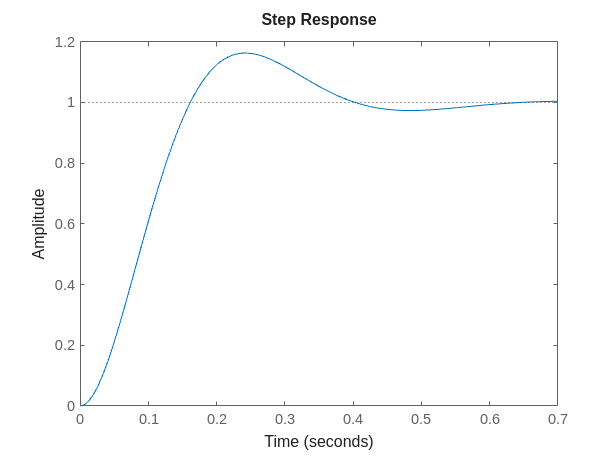

step(Ge)

stepinfo(Ge)

ans = struct with fields:
         RiseTime: 0.1093
    TransientTime: 0.5384
     SettlingTime: 0.5384
      SettlingMin: 0.9315
      SettlingMax: 1.1629
        Overshoot: 16.2929
       Undershoot: 0
             Peak: 1.1629
         PeakTime: 0.2395


## Nise 5.14

See Textbook solutions 